imgOG = imread("girlpearl.jpg");
fprintf("Original Image:\n")

Original Image:


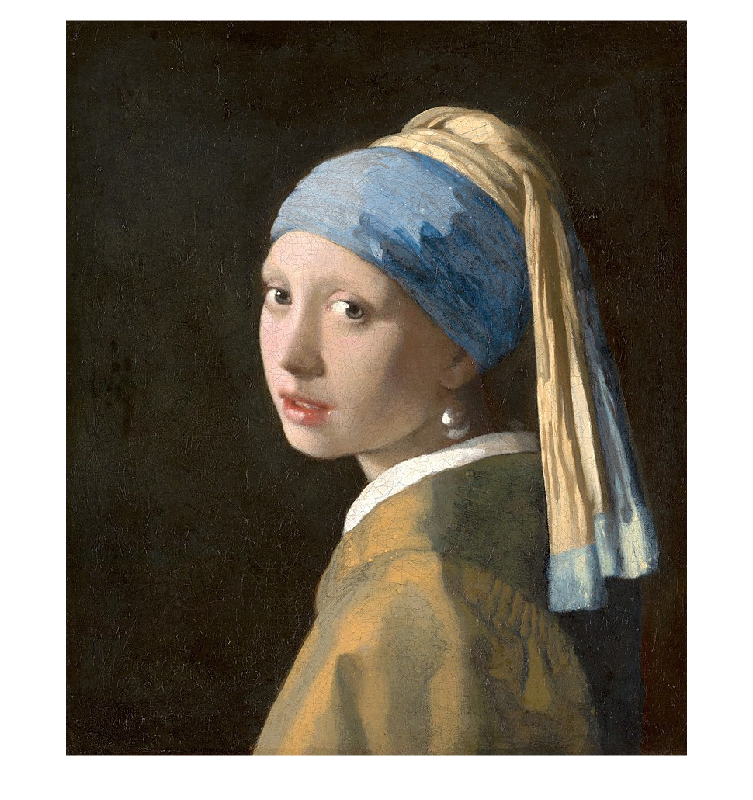

imshow(imgOG)

sizeOG = size(imgOG);
[n,d]=rat(sizeOG(2)/sizeOG(1),.05);
fprintf("Aspect Ratio For Original Image is %d:%d.\n", n,d)

Aspect Ratio For Original Image is 5:6.


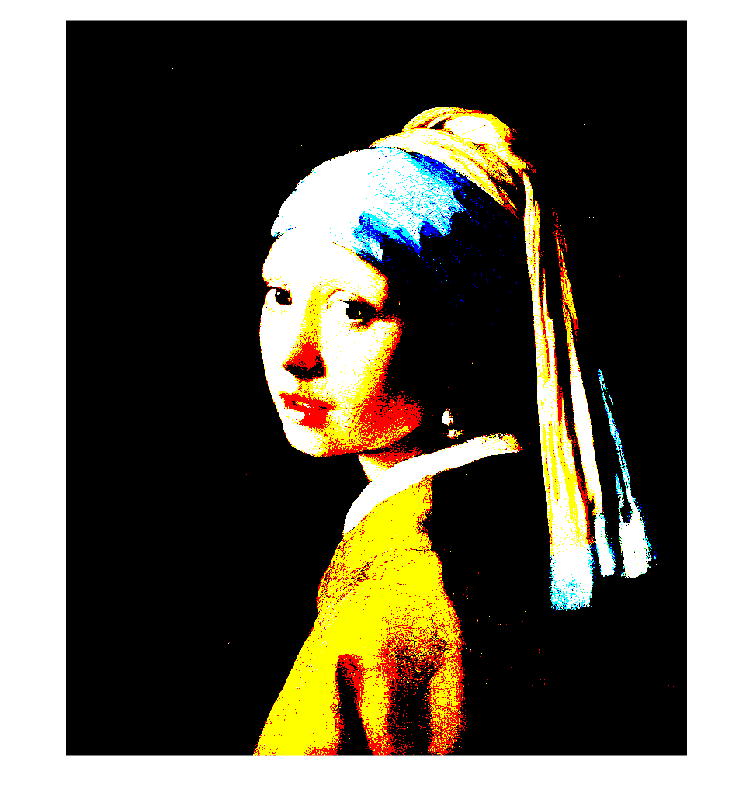

%numCol = 100;
%numRow = numCol*(n/d);
imgSmall = imresize(imgOG, [sizeOG(1), sizeOG(2)], "nearest");
[X, map] = rgb2ind(imgSmall, 0.8,"nodither");
%[imgFinal, mapf] = imresize(X, map,(1/0.02), "nearest");
%fprintf("Pattern:")
imshow(X, map);

fprintf("Size of pattern is %d columns x %d rows.\n",numCol,numRow)

Size of pattern is 100 columns x 100 rows.


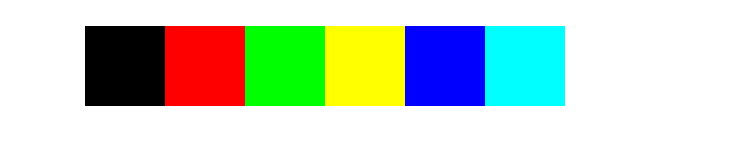

imgColorKey  = 1:length(map);
[ICK, mapck] = imresize(imgColorKey, map,80,"nearest");
imshow(ICK, map)

patternRBG = ind2rgb(imgFinal, mapf);